% Define las ecuaciones diferenciales
syms x y

% Exercise 3
% We use a small positive constant to handle the division by zero error
eps = 1e-10;

fx = x*(1 - (x/7)) - (6*x*y) / (7 + (7*x))

$$fx = -x\,\left(\frac{x}{7}-1\right)-\frac{6\,x\,y}{7\,x+7}$$

fy = 0.2*y*(1 - (0.5*y/(x+eps)))

$$fy = -\frac{y\,\left(\frac{y}{2\,\left(x+\frac{1}{10000000000}\right)}-1\right)}{5}$$

% setting the matlab function for our system -> Use max(z(1), eps) to avoid division by zero
f_lmb = @(t, z) [
     z(1)*(1 - z(1)/7) - ((6*z(1)*z(2))/(7 + 7*z(1)));
     0.2*z(2)*(1 - (0.5*z(2)/(z(1) + eps))); 
];

% 1. CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: [5×1 sym]
    y: [5×1 sym]


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =          0    7.0000   -7.0000    1.0000         0
         0         0  -14.0000    2.0000    0.0000



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts, 2));

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% 2. IDENTIFY IF THE FIXED POINTS ARE HYPERBOLIC
% 3. CLASSIFICATION OF THE FIXED POINTS
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) == 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.000000, 0.000000) is not hyperbolic.
Fixed point at (7.000000, 0.000000) is not hyperbolic.
Fixed point at (-7.000000, -14.000000) is not hyperbolic.
Fixed point at (1.000000, 2.000000) is not hyperbolic.
Fixed point at (0.000000, 0.000000) is not hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');


% 4. COMPUTE THE NULLCLINES
xcline_x = solve(fx == 0, x);
ycline_y = solve(fy == 0, y);

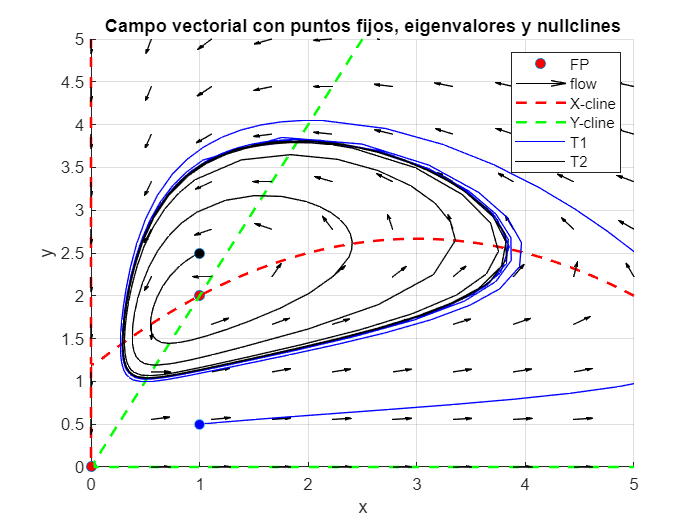


% Representing the nullclines
nullX = fimplicit(fx, [-eps 5 -eps 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-eps 5 -eps 5], 'g--', 'LineWidth', 1.5);

% 6. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(0, 5, N);
ylin = linspace(0, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);
% Computing the grid
fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing the flow of the system with quiver
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-eps 5 -eps 5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

% 7. DRAW THE PHASE PORTRAIT
% 5. REPRESENT A TRAJECTORY
t0 = 0.5; tf = 100;
tspam = [t0,tf];

% Initialise at (1, 0.5)
y0 =[1 0.5];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Initialise at (0.5, 2)
y0 =[1 2.5];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'black-'); plot(y0(1),y0(2),'o','MarkerFaceColor','black');

legend([fpts flow nullX nullY traj1 traj2], ...
    {'FP', 'flow', 'X-cline', 'Y-cline', 'T1', 'T2'}, ...
    'Location', 'NorthEast')


disp(['We will see that such a model has a limiting cycle, because if prey start to ' ...
    'multiply, resources start to run out and predators start to increase. ' ...
    'On the other hand, if prey become scarce, the smaller the predator population ' ...
    'will be and the more resources there will be to increase their growth.'])

We will see that such a model has a limiting cycle, because if prey start to multiply, resources start to run out and predators start to increase. On the other hand, if prey become scarce, the smaller the predator population will be and the more resources there will be to increase their growth.



% Convert hexadecimal color code to RGB triplet
hexColor = '#A2142F';
rgbColor = sscanf(hexColor(2:end), '%2x') / 255;  % Convert hexadecimal to RGB